# 4. Printing

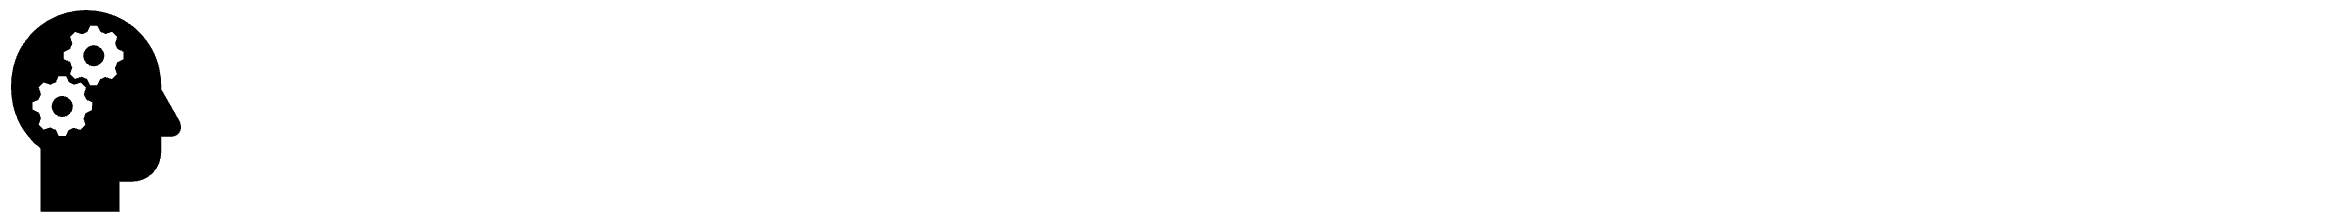

Printing is displaying values to the terminal. You use the built in Matlab **functions** `disp()` or `fprintf()` to display values.

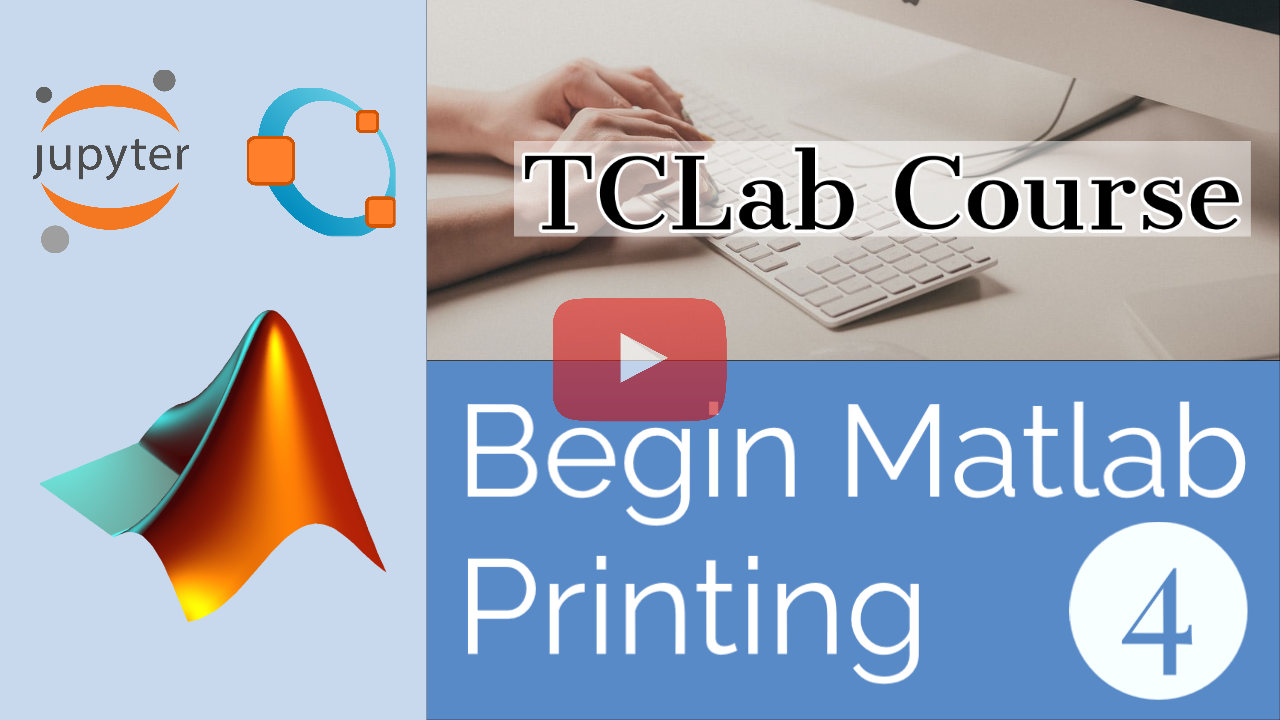

[Click here to watch the video: Matlab 👩‍💻 Printing disp and fprintf](https://www.youtube.com/watch?v=Y3-YCV76Ufg)

You could use print statements update the current temperature of the incubator. Get more practice by putting something different in the function and running the program.

T = 37.2;
disp(['The temperature of the egg is ',num2str(T)])

The temperature of the egg is 37.2


fprintf('The temperature of the egg is %.2f',T)

The temperature of the egg is 37.20

You can also print other information such as the type of a variable with `class()`.

eggs = 200 % integer variable

eggs = 200

disp(class(eggs))

double


egg_type = "Platypus" % string variable

egg_type = "Platypus"

disp(class(egg_type))

string


yes = true % Boolean variable

yes = logical
   1


disp(class(yes))

logical


Now using information from the previous lesson, combine different value types by displaying a `double` and a `char` together. This is similar but instead of putting them in a variable, you are displaying them to the screen. You'll have to change the value type for it to work like in the previous activity such as `num2str()` to convert a number to a string. You can also convert a string to a number with `str2num()`.

myNumberString = '62'

myNumberString = '62'

class(myNumberString)

ans = 'char'

myNumberInt = str2num(myNumberString)

myNumberInt = 62

class(myNumberInt)

ans = 'double'

disp([myNumberString,myNumberInt]) % Print a string and number together, correctly

62>


You can use two **variables** in a `disp` function by doing something like this `disp([var1, var2])`. If you want more practice put different strings into the **variables**.

var1 = 'Put something here'

var1 = 'Put something here'

var2 = " and put something here." 

var2 = " and put something here."

disp([var1, var2]) % Prints both

    "Put something here"    " and put something here."



You can also use commas to separate things when displaying but they must always be the same type (e.g. no mixing `char` and `double`). Use `%.0f` to display the integer portion of the number in `fprintf`.

T = 45.7

T = 45.7000

disp(["You are cooking the egg at ", int2str(T), "°C, cool down!"])

    "You are cooking the egg at "    "46"    "°C, cool down!"



fprintf('You are cooking the egg at %.0f°C, cool down!',T)

You are cooking the egg at 46°C, cool down!

### **Displaying Results**

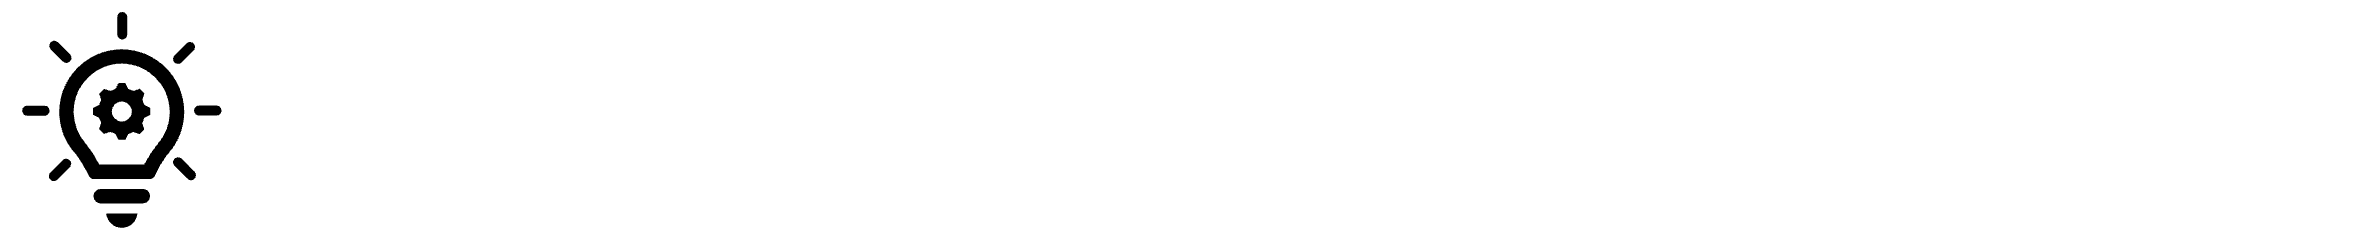

Jupyter Notebook automatically displays the expressions in a cell that do not end with a semi-colon `;`. Removing the `;` is useful when you need to display the output. Run the code below and put in different equations to check your understanding.

3*5

ans = 15

5*2;

Another way to ensure display is to use a `disp()` function and you can get output for the line.

disp(14/2)

     7



disp(7*2)

    14



disp(3+11)

    14



### **Activity**

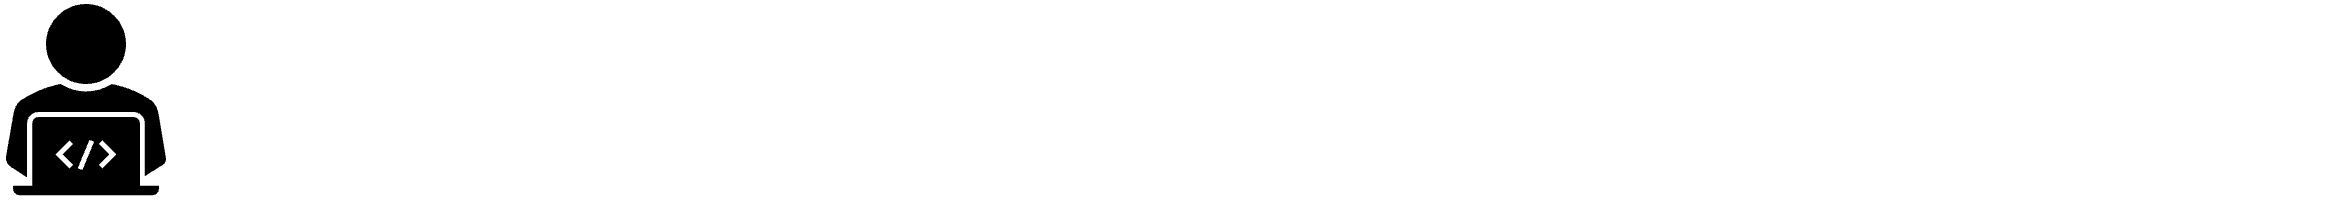

Make two **variables** that will add two numbers when you print them together. This is kind of like the example above, but use numbers in your variables.

% First number variable        
    % Second number variable
disp("")  % Print together

If you assign the same variable twice it simply changes values.

`    test` `=` `3`

`    test` `=` `"egg"`

Do the same here, except now print the variable and `class()` in between variable assignments so you can see how it works.

test = 3;       % display here
test = "egg";   % display here

Use the variable with an equation to display 500. You need to make the `disp()` have an equation in order to change the output value.

equation = 25*4

equation = 100

disp(equation    ) % Make an equation to equal 500

   100



Connect the USB communication cable to the Arduino. The white power cable is not needed for this exercise.

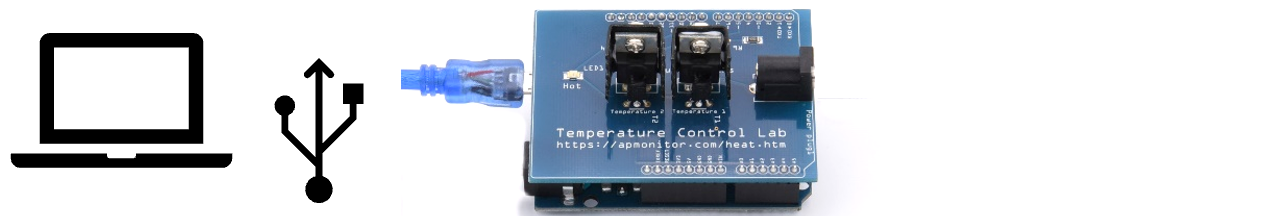

Calculate the median of 3 temperature values. Connect to the TCLab with `lab=tclab`, read the temperature values 3 times with `lab.T1`, store the values in variables `TC1`, `TC2`, and `TC3`, and display the median of the 3 values. Close the connection to the TCLab with `clear lab`.

Create a single line that displays the 3 values and the median such as:

`    The` `median` `of` `23.52``,` `23.23``,` `and` `23.74` `is` `23.52``.`

You can combine the numbers by creating an Array such as

`    disp``([``"The median of "``,` `num2str``(``TC1``),` `", "``,` `num2str``(``TC2``),` `", ..."``])`

clear all
lab = tclab;

Unrecognized function or variable 'tclab'.

TC1=lab.T1; TC2=lab.T1; TC3=lab.T1;
TM = median([TC1,TC2,TC3])
clear lab